load('new_plant_gyro_elev.mat')
load('LAG_notch_elev_tacho.mat')
load('new_notch_35hz_elev_gyro.mat')
load('new_notch_70hz_elev_gyro.mat')
load('new_notch_elev_gyro_100hz.mat')
load('new_notch_15hz_elev_gyro.mat')
load('notch_elev_gyro_20.mat')
load("LAG_elev_gyro.mat")

options = bodeoptions;
options.FreqUnits = 'Hz';


gain_elev_gyro = 0.5;

figure;
load('new_plant_gyro_elev.mat')
bode(simulation_elev_gyro_plant);
%sisotool(simulation_elev_gyro_plant)
hold on
bode(sys_mes_elev_gyro,options)
xlim([3,1000])
legend('Simulation','Mesurmants')

hold off;grid on

## PRINT

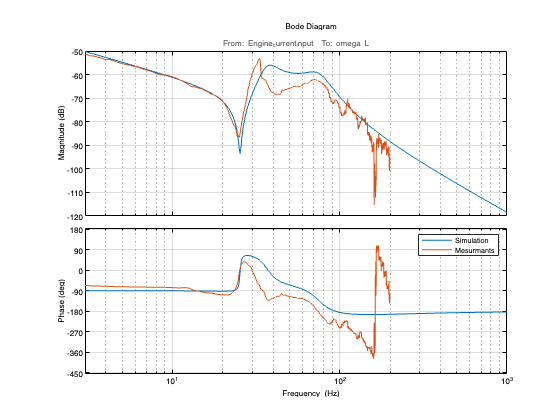

saveas(gcf,'/Users/ohadformanair/Documents/project_plots/elev_gyro_plant_sim_mes.png')

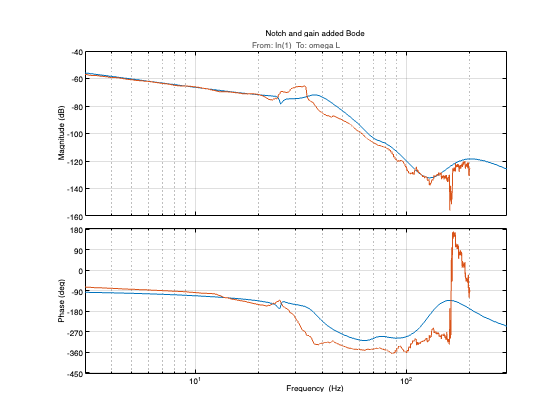

figure;


elev_gyro_notch =new_notch_35hz_elev_gyro*new_notch_70hz_elev_gyro*new_notch_elev_gyro_100hz*new_notch_15hz_elev_gyro;
elev_gyro_sim = tf(simulation_elev_gyro_plant*elev_gyro_notch*gain_elev_gyro*notch_elev_gyro_20);
elev_gyro_mes = sys_mes_elev_gyro*elev_gyro_notch*gain_elev_gyro*notch_elev_gyro_20;



bode(elev_gyro_sim,options);
hold on;
bode(elev_gyro_mes,options)
title('Notch and gain added Bode')
grid on
hold off
xlim([3,300])

figure;

opts = pidtuneOptions('PhaseMargin',80);
[C_pi_elev_gyro,info] = pidtune(elev_gyro_sim,'PI',55,opts)

C_pi_elev_gyro =
 
             1 
  Kp + Ki * ---
             s 

  with Kp = 1.83e+03, Ki = 1.76e+03
 
Continuous-time PI controller in parallel form.



info = struct with fields:
                Stable: 1
    CrossoverFrequency: 55
           PhaseMargin: 69.6926



Kp_elev_gyro = C_pi_elev_gyro.Kp+500;
Ki_elev_gyro = C_pi_elev_gyro.Ki/40;
%Kd_elev_gyro = C_pi_elev_gyro.Kd;
PI_elev_gyro = tf(1/s*Ki_elev_gyro+Kp_elev_gyro);

sys_control = PI_elev_gyro*elev_gyro_sim;

figure;
margin(sys_control*LAG_notch_elev_tacho)
xlim([1,200])
grid on

## PRINT

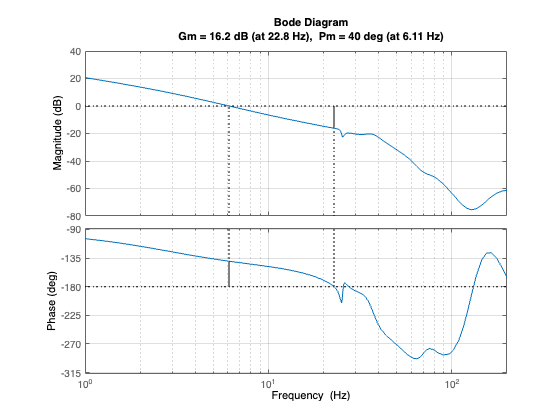

saveas(gcf,'/Users/ohadformanair/Documents/project_plots/elev_gyro_sim_controlled.png')

allmargin(sys_control)

ans = struct with fields:
     GainMargin: [1.7130 1.7235e+03 358.9165]
    GMFrequency: [225.6420 836.7580 1.3107e+03]
    PhaseMargin: 65.5765
    PMFrequency: 70.2122
    DelayMargin: 0.0163
    DMFrequency: 70.2122
         Stable: 1


figure;
margin(elev_gyro_mes*PI_elev_gyro*LAG_notch_elev_tacho)
grid on
xlim([1,200])

## PRINT

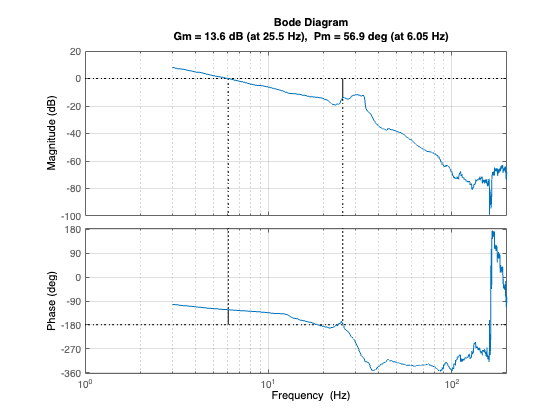

saveas(gcf,'/Users/ohadformanair/Documents/project_plots/elev_gyro_mes_controlled.png')

PC_elev_gyro = sys_control;
elev_gyro_notch = tf(elev_gyro_notch*LAG_notch_elev_tacho*notch_elev_gyro_20);